# BO4CO (Bayesian Optimization for Configuration Optimization)

BO4CO is a Configuration Optimization Tool for Big Data Systems. 

This script uses synthetic functions as response instead of experimental measurements, this is only for demonstration of the underlying machine learning method, more details: [https://arxiv.org/abs/1606.06543](https://arxiv.org/abs/1606.06543)

When referring to the dataset or code please cite the paper:

**P. Jamshidi, G. Casale, "An Uncertainty-Aware Approach to Optimal Configuration of Stream Processing Systems", MASCOTS 2016.**

*@inproceedings{jamshidi2016bo4co,*

*	title={An Uncertainty-Aware Approach to Optimal Configuration of Stream Processing Systems.},*

*	author={Jamshidi, Pooyan and Casale, Giuliano},*

*	booktitle={MASCOTS},*

*	year={2016}*

*}*

Authors: Pooyan Jamshidi (pooyan.jamshidi@gmail.com)

The code is released under the FreeBSD License.

Copyright (C) 2016 Imperial College London

Home: [https://github.com/pooyanjamshidi](https://github.com/pooyanjamshidi)

**Complementary materials** 

- [Paper](https://arxiv.org/pdf/1606.06543v1) is the key paper about BO4CO.

- [Wiki](https://github.com/dice-project/DICE-Configuration-BO4CO) provides more details about the tool and setting up the environment.

- [Data](https://zenodo.org/record/56238) is the experimental datasets.

- [Presentation](http://www.slideshare.net/pooyanjamshidi/transfer-learning-for-optimal-configuration-of-big-data-software) is a presentation about the tool and our experimental results.

- [Gitxiv](http://gitxiv.com/posts/5XkMY4C3hXScwZ3Tw/an-uncertainty-aware-approach-to-optimal-configuration-of) is all research materials about the tool in one link.

- [TL4CO](https://github.com/dice-project/DICE-Configuration-TL4CO) is the DevOps enabled configuration optimization tool.

## Initilizations

close all;
clear variables;
clc;
warning off;

global nMinGridPoints istestfun

nMinGridPoints=1e4; % regular grid size  
istestfun=1; % is it a synthetic function?
maxExp=1; % only 1 experiment
visualize=1;
maxIter=20;
nInit=4; % Initial samples from the Latin Hypercube design

Fmotion = @(x) alpha(max(min(x,1),0)); % for transparent fill and fun!

## The synthetic function we want to find it's optimum (a wrapper for the response function)

if istestfun
    [f, domain, trueMinLoc] = testFunctionFactory('e4'); %f11 e4
else
    [f, domain, trueMinLoc] = testConfigurationFactory('cass20-109'); %f11 e4
end

d = size(domain, 1) % dimension of the space

d = 1

## Initialize the prior

choose the covariance function as you wish 11 is the MaternARD and 8 is SE-ARD, 1 is SE-iso and 2,3,4 are Matern-iso 1-3-5 respectively see some descriptions about the kernels here: [http://www.cs.toronto.edu/~duvenaud/cookbook/index.html](http://www.cs.toronto.edu/~duvenaud/cookbook/index.html) some more details in [https://arxiv.org/abs/1606.06543](https://arxiv.org/abs/1606.06543)

gps = covarianceKernelFactory(11, d)

gps =         meanfunc: @meanConst
             hyp: [1×1 struct]
    hypgridRange: [1×1 struct]
         covfunc: {@covCaching  {1×2 cell}}
         likfunc: @likGauss
         hypgrid: [1×72 struct]


## Bayesian Optimization loop (iterative design of experiments)

The result figures shows the estimation of the response function (the synthetic function we chose above) using Gaussian Process models. Here we boLCB choose the next point based on LCB criteria to evaluate the function. In each iteration, we gain some knowledge about the true function and as the figure shows GP models provide a better estimations of the underlying function. As we have shown in the paper, GP models provide more accurate prediction of the underlying response function comparing with other machine learning regression models, see  [https://arxiv.org/abs/1606.06543](https://arxiv.org/abs/1606.06543).

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 8.706325e-02
Function evaluation      3;  Value -5.923743e-01
Function evaluation      4;  Value -1.235363e+00
Function evaluation      7;  Value -1.251189e+00
Function evaluation     10;  Value -1.310655e+00
Function evaluation     12;  Value -1.439220e+00
Function evaluation     15;  Value -1.490940e+00
Function evaluation     17;  Value -1.517963e+00
Function evaluation     19;  Value -1.522317e+00
Function evaluation     21;  Value -1.531357e+00
Function evaluation     24;  Value -1.531729e+00
Function evaluation     26;  Value -1.531760e+00
Function evaluation     30;  Value -1.531760e+00
Function evaluation     38;  Value -1.531966e+00
Function evaluation     40;  Value -1.531993e+00
Function evaluation     42;  Value -1.532002e+00
Function evaluation     44;  Value -1.532002e+00
Function evaluation     46;  Value -1.532002e+00
Function evaluation     48;  Value -1.532002e+00
Function evaluation 

Grid point is better than previous hyperparameter
Function evaluation      0;  Value -1.132024e+00
Function evaluation      4;  Value -2.253425e+00
Function evaluation      7;  Value -2.819165e+00
Function evaluation     11;  Value -2.862980e+00
Function evaluation     13;  Value -2.902577e+00
Function evaluation     15;  Value -3.004244e+00
Function evaluation     17;  Value -3.072468e+00
Function evaluation     18;  Value -3.134898e+00
Function evaluation     20;  Value -3.155298e+00
Function evaluation     22;  Value -3.168437e+00
Function evaluation     24;  Value -3.175488e+00
Function evaluation     27;  Value -3.207558e+00
Function evaluation     29;  Value -3.251265e+00
Function evaluation     32;  Value -3.386790e+00
Function evaluation     36;  Value -3.403071e+00
Function evaluation     38;  Value -3.426975e+00
Function evaluation     41;  Value -3.427270e+00
Function evaluation     44;  Value -3.428362e+00
Function evaluation     46;  Value -3.430365e+00
Function evaluation

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 6.327352e-02
Function evaluation      3;  Value -2.895903e-01
Function evaluation      5;  Value -5.117538e-01
Function evaluation      8;  Value -5.531813e-01
Function evaluation     11;  Value -8.087535e-01
Function evaluation     16;  Value -8.845779e-01
Function evaluation     18;  Value -9.955215e-01
Function evaluation     20;  Value -1.198629e+00
Function evaluation     23;  Value -1.214238e+00
Function evaluation     25;  Value -1.255263e+00
Function evaluation     27;  Value -1.301560e+00
Function evaluation     30;  Value -1.311497e+00
Function evaluation     32;  Value -1.312539e+00
Function evaluation     34;  Value -1.312659e+00
Function evaluation     36;  Value -1.312665e+00
Function evaluation     38;  Value -1.312670e+00
Function evaluation     40;  Value -1.312679e+00
Function evaluation     42;  Value -1.312690e+00
Function evaluation     44;  Value -1.312713e+00
Function evaluation 

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 4.298096e-01
Function evaluation      3;  Value 1.345155e-01
Function evaluation      5;  Value 1.081105e-01
Function evaluation      8;  Value -9.502561e-02
Function evaluation     10;  Value -1.825246e-01
Function evaluation     12;  Value -2.219224e-01
Function evaluation     15;  Value -4.669078e-01
Function evaluation     18;  Value -5.149458e-01
Function evaluation     20;  Value -5.259475e-01
Function evaluation     22;  Value -5.296370e-01
Function evaluation     23;  Value -5.331823e-01
Function evaluation     24;  Value -5.367199e-01
Function evaluation     26;  Value -5.397974e-01
Function evaluation     28;  Value -5.441663e-01
Function evaluation     30;  Value -5.462664e-01
Function evaluation     32;  Value -5.495862e-01
Function evaluation     34;  Value -5.514451e-01
Function evaluation     36;  Value -5.543262e-01
Function evaluation     38;  Value -5.553812e-01
Function evaluation   

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 3.578230e-01
Function evaluation      2;  Value -1.444333e-01
Function evaluation      5;  Value -1.587582e-01
Function evaluation      9;  Value -3.434727e-01
Function evaluation     11;  Value -4.127059e-01
Function evaluation     13;  Value -4.422889e-01
Function evaluation     18;  Value -7.086284e-01
Function evaluation     21;  Value -7.355737e-01
Function evaluation     23;  Value -7.414894e-01
Function evaluation     25;  Value -7.417463e-01
Function evaluation     27;  Value -7.422867e-01
Function evaluation     29;  Value -7.425143e-01
Function evaluation     31;  Value -7.425475e-01
Function evaluation     33;  Value -7.425620e-01
Function evaluation     36;  Value -7.426209e-01
Function evaluation     40;  Value -7.439309e-01
Function evaluation     42;  Value -7.456836e-01
Function evaluation     44;  Value -7.466368e-01
Function evaluation     45;  Value -7.476515e-01
Function evaluation 

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 2.850996e-01
Function evaluation      3;  Value -4.955443e-01
Function evaluation      6;  Value -5.046596e-01
Function evaluation     10;  Value -7.425395e-01
Function evaluation     13;  Value -7.637312e-01
Function evaluation     16;  Value -8.703829e-01
Function evaluation     18;  Value -1.005863e+00
Function evaluation     22;  Value -1.024600e+00
Function evaluation     24;  Value -1.044915e+00
Function evaluation     26;  Value -1.047662e+00
Function evaluation     28;  Value -1.050831e+00
Function evaluation     30;  Value -1.051524e+00
Function evaluation     32;  Value -1.052099e+00
Function evaluation     34;  Value -1.053045e+00
Function evaluation     36;  Value -1.054207e+00
Function evaluation     39;  Value -1.062706e+00
Function evaluation     41;  Value -1.063907e+00
Function evaluation     43;  Value -1.064328e+00
Function evaluation     46;  Value -1.066507e+00
Function evaluation 

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 4.631506e-01
Function evaluation      3;  Value -2.036544e-01
Function evaluation      6;  Value -4.690996e-01
Function evaluation      9;  Value -5.608855e-01
Function evaluation     11;  Value -6.394176e-01
Function evaluation     13;  Value -7.523213e-01
Function evaluation     17;  Value -7.675898e-01
Function evaluation     20;  Value -8.360903e-01
Function evaluation     23;  Value -8.376642e-01
Function evaluation     25;  Value -8.400973e-01
Function evaluation     27;  Value -8.440989e-01
Function evaluation     30;  Value -8.613305e-01
Function evaluation     31;  Value -8.786696e-01
Function evaluation     33;  Value -8.839845e-01
Function evaluation     35;  Value -8.859243e-01
Function evaluation     38;  Value -8.931383e-01
Function evaluation     40;  Value -8.953510e-01
Function evaluation     42;  Value -8.957595e-01
Function evaluation     44;  Value -8.959441e-01
Function evaluation 

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 9.776425e-01
Function evaluation      3;  Value 3.341801e-01
Function evaluation      7;  Value 2.579312e-01
Function evaluation      9;  Value 4.919214e-02
Function evaluation     12;  Value 3.190245e-02
Function evaluation     14;  Value 1.911893e-02
Function evaluation     16;  Value 1.782668e-02
Function evaluation     17;  Value 1.657592e-02
Function evaluation     19;  Value 1.478776e-02
Function evaluation     23;  Value -5.530903e-03
Function evaluation     25;  Value -2.114051e-02
Function evaluation     27;  Value -4.339881e-02
Function evaluation     29;  Value -4.728960e-02
Function evaluation     33;  Value -7.456925e-02
Function evaluation     35;  Value -7.890464e-02
Function evaluation     37;  Value -7.897052e-02
Function evaluation     39;  Value -7.898239e-02
Function evaluation     41;  Value -7.902146e-02
Function evaluation     44;  Value -7.902387e-02
Function evaluation     46; 

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 7.426323e-01
Function evaluation      3;  Value -9.769217e-02
Function evaluation      6;  Value -1.307215e-01
Function evaluation      9;  Value -2.357981e-01
Function evaluation     12;  Value -2.377924e-01
Function evaluation     17;  Value -3.269013e-01
Function evaluation     19;  Value -3.388300e-01
Function evaluation     22;  Value -3.884772e-01
Function evaluation     24;  Value -4.217563e-01
Function evaluation     26;  Value -4.342976e-01
Function evaluation     28;  Value -4.371455e-01
Function evaluation     30;  Value -4.377743e-01
Function evaluation     32;  Value -4.397942e-01
Function evaluation     34;  Value -4.406444e-01
Function evaluation     36;  Value -4.408897e-01
Function evaluation     38;  Value -4.410464e-01
Function evaluation     40;  Value -4.411050e-01
Function evaluation     42;  Value -4.411981e-01
Function evaluation     46;  Value -4.427548e-01
Function evaluation 

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 1.381394e+00
Function evaluation      2;  Value 8.793188e-01
Function evaluation      5;  Value 6.886135e-01
Function evaluation      7;  Value 6.413046e-01
Function evaluation      9;  Value 6.012218e-01
Function evaluation     11;  Value 5.735614e-01
Function evaluation     14;  Value 5.716144e-01
Function evaluation     18;  Value 5.385888e-01
Function evaluation     20;  Value 4.987027e-01
Function evaluation     22;  Value 4.523255e-01
Function evaluation     24;  Value 3.975203e-01
Function evaluation     27;  Value 3.955238e-01
Function evaluation     28;  Value 3.934919e-01
Function evaluation     29;  Value 3.916185e-01
Function evaluation     32;  Value 3.914550e-01
Function evaluation     33;  Value 3.912972e-01
Function evaluation     35;  Value 3.911927e-01
Function evaluation     37;  Value 3.911609e-01
Function evaluation     40;  Value 3.910228e-01
Function evaluation     42;  Value 3.9

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 1.236763e+00
Function evaluation      3;  Value 5.224106e-01
Function evaluation      6;  Value 3.099384e-01
Function evaluation      8;  Value 1.980747e-01
Function evaluation     11;  Value 1.893882e-01
Function evaluation     13;  Value 1.826522e-01
Function evaluation     17;  Value 3.437906e-02
Function evaluation     19;  Value 7.142030e-03
Function evaluation     21;  Value -7.280523e-03
Function evaluation     23;  Value -8.791793e-03
Function evaluation     25;  Value -1.135327e-02
Function evaluation     27;  Value -1.258393e-02
Function evaluation     29;  Value -1.278291e-02
Function evaluation     31;  Value -1.290082e-02
Function evaluation     32;  Value -1.301329e-02
Function evaluation     35;  Value -1.410007e-02
Function evaluation     37;  Value -1.429063e-02
Function evaluation     41;  Value -1.645563e-02
Function evaluation     44;  Value -1.660427e-02
Function evaluation     46;

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 4.360161e+00
Function evaluation      3;  Value 4.198449e+00
Function evaluation      5;  Value 4.054402e+00
Function evaluation      9;  Value 4.035029e+00
Function evaluation     11;  Value 4.033011e+00
Function evaluation     14;  Value 4.024682e+00
Function evaluation     17;  Value 3.970726e+00
Function evaluation     19;  Value 3.957376e+00
Function evaluation     21;  Value 3.944992e+00
Function evaluation     23;  Value 3.939166e+00
Function evaluation     25;  Value 3.936339e+00
Function evaluation     27;  Value 3.936259e+00
Function evaluation     29;  Value 3.936243e+00
Function evaluation     31;  Value 3.936227e+00
Function evaluation     33;  Value 3.936225e+00
Function evaluation     39;  Value 3.935604e+00
Function evaluation     41;  Value 3.935288e+00
Function evaluation     43;  Value 3.935119e+00
Function evaluation     46;  Value 3.934116e+00
Function evaluation     49;  Value 3.9

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 4.228007e+00
Function evaluation      3;  Value 3.993552e+00
Function evaluation      7;  Value 3.917571e+00
Function evaluation      9;  Value 3.888440e+00
Function evaluation     11;  Value 3.883726e+00
Function evaluation     13;  Value 3.876019e+00
Function evaluation     16;  Value 3.832923e+00
Function evaluation     18;  Value 3.802903e+00
Function evaluation     20;  Value 3.799805e+00
Function evaluation     22;  Value 3.790477e+00
Function evaluation     24;  Value 3.787373e+00
Function evaluation     26;  Value 3.786804e+00
Function evaluation     28;  Value 3.786693e+00
Function evaluation     30;  Value 3.786658e+00
Function evaluation     32;  Value 3.786576e+00
Function evaluation     34;  Value 3.786558e+00
Function evaluation     36;  Value 3.786537e+00
Function evaluation     38;  Value 3.786534e+00
Function evaluation     41;  Value 3.786510e+00
Function evaluation     43;  Value 3.7

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 5.832216e+00
Function evaluation      3;  Value 5.647221e+00
Function evaluation      5;  Value 5.514304e+00
Function evaluation      7;  Value 5.401692e+00
Function evaluation     10;  Value 5.396896e+00
Function evaluation     12;  Value 5.394685e+00
Function evaluation     13;  Value 5.392554e+00
Function evaluation     16;  Value 5.381811e+00
Function evaluation     18;  Value 5.379612e+00
Function evaluation     20;  Value 5.372416e+00
Function evaluation     22;  Value 5.357788e+00
Function evaluation     24;  Value 5.348839e+00
Function evaluation     26;  Value 5.345863e+00
Function evaluation     28;  Value 5.345128e+00
Function evaluation     30;  Value 5.344192e+00
Function evaluation     32;  Value 5.343435e+00
Function evaluation     34;  Value 5.341704e+00
Function evaluation     36;  Value 5.341381e+00
Function evaluation     39;  Value 5.339868e+00
Function evaluation     42;  Value 5.3

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 5.690828e+00
Function evaluation      3;  Value 5.544882e+00
Function evaluation      4;  Value 5.405785e+00
Function evaluation      6;  Value 5.322952e+00
Function evaluation      8;  Value 5.315558e+00
Function evaluation     10;  Value 5.313198e+00
Function evaluation     12;  Value 5.308006e+00
Function evaluation     14;  Value 5.307062e+00
Function evaluation     18;  Value 5.287780e+00
Function evaluation     20;  Value 5.270760e+00
Function evaluation     22;  Value 5.266074e+00
Function evaluation     25;  Value 5.238101e+00
Function evaluation     27;  Value 5.231444e+00
Function evaluation     29;  Value 5.226114e+00
Function evaluation     32;  Value 5.225936e+00
Function evaluation     34;  Value 5.225915e+00
Function evaluation     36;  Value 5.225914e+00
Function evaluation     39;  Value 5.225909e+00
Function evaluation     41;  Value 5.225901e+00
Function evaluation     43;  Value 5.2

Grid point is better than previous hyperparameter
Function evaluation      0;  Value 5.140076e+00
Function evaluation      3;  Value 5.069877e+00
Function evaluation      5;  Value 5.050334e+00
Function evaluation      7;  Value 5.023891e+00
Function evaluation      9;  Value 5.015511e+00
Function evaluation     12;  Value 4.947940e+00
Function evaluation     14;  Value 4.865926e+00
Function evaluation     16;  Value 4.846470e+00
Function evaluation     18;  Value 4.841480e+00
Function evaluation     20;  Value 4.839714e+00
Function evaluation     22;  Value 4.837289e+00
Function evaluation     24;  Value 4.836513e+00
Function evaluation     26;  Value 4.836040e+00
Function evaluation     28;  Value 4.835799e+00
Function evaluation     31;  Value 4.834674e+00
Function evaluation     33;  Value 4.831671e+00
Function evaluation     35;  Value 4.826541e+00
Function evaluation     37;  Value 4.823632e+00
Function evaluation     39;  Value 4.821423e+00
Function evaluation     41;  Value 4.8

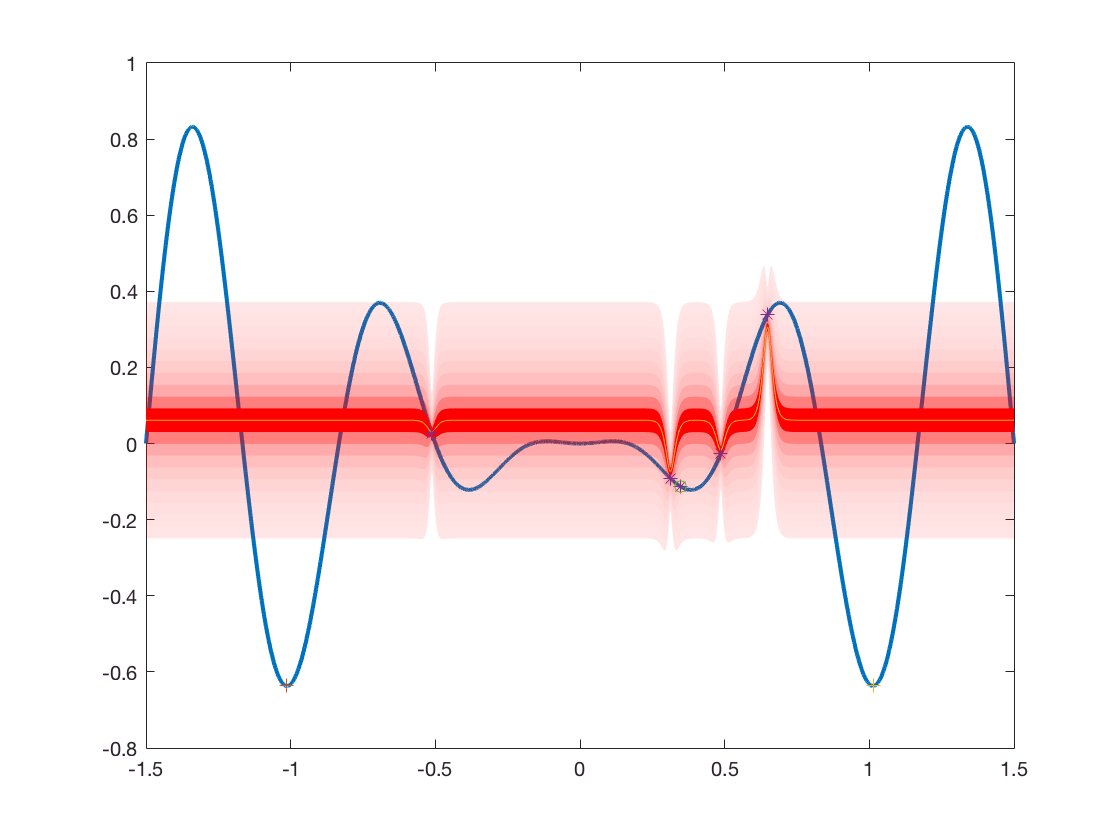

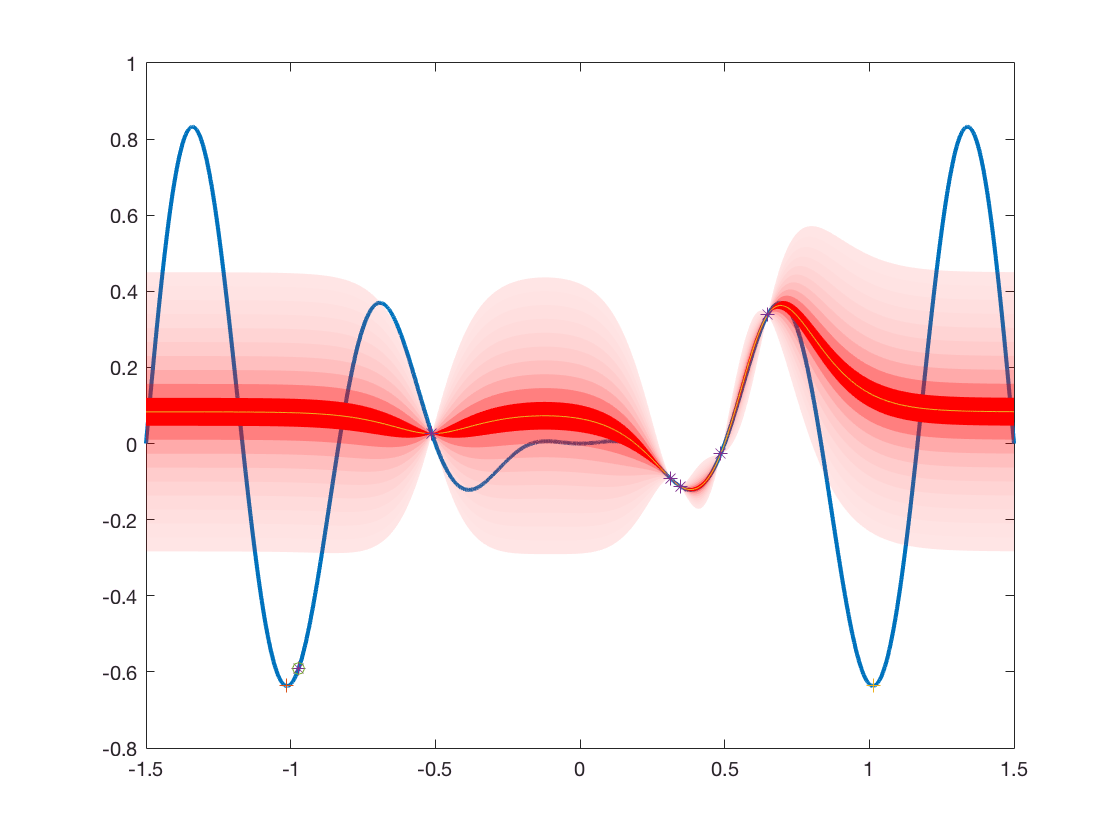

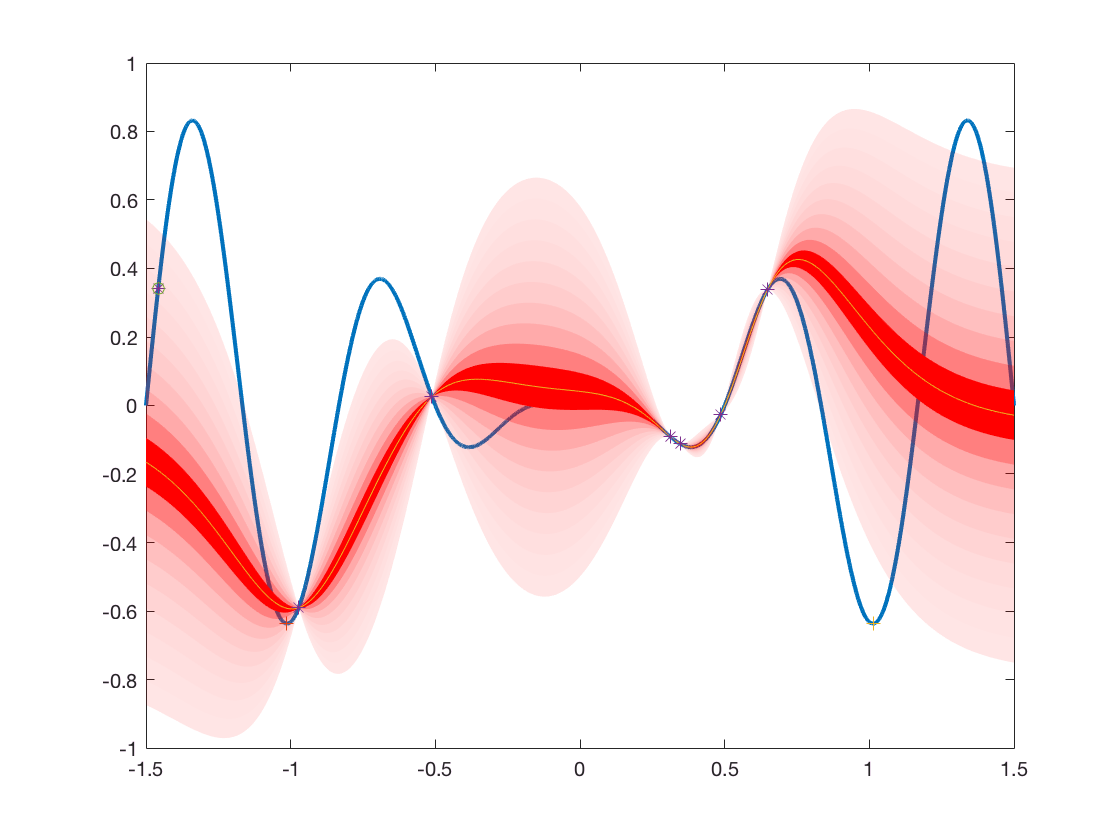

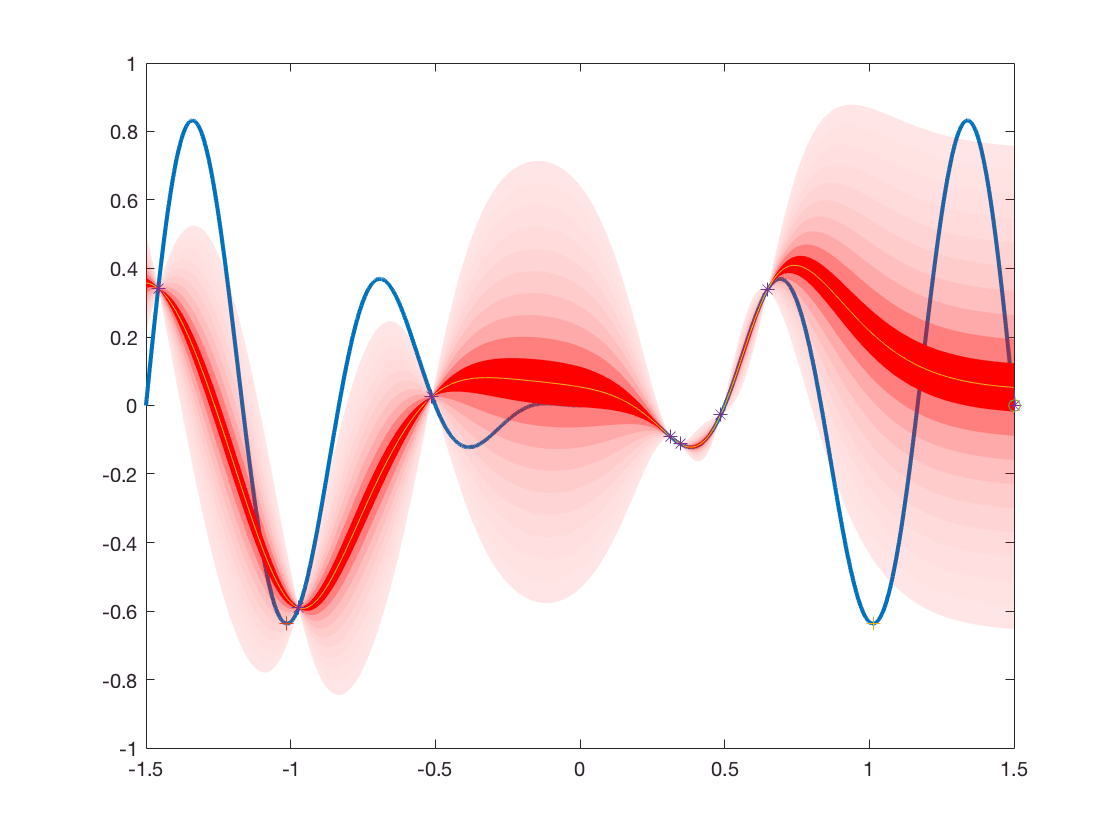

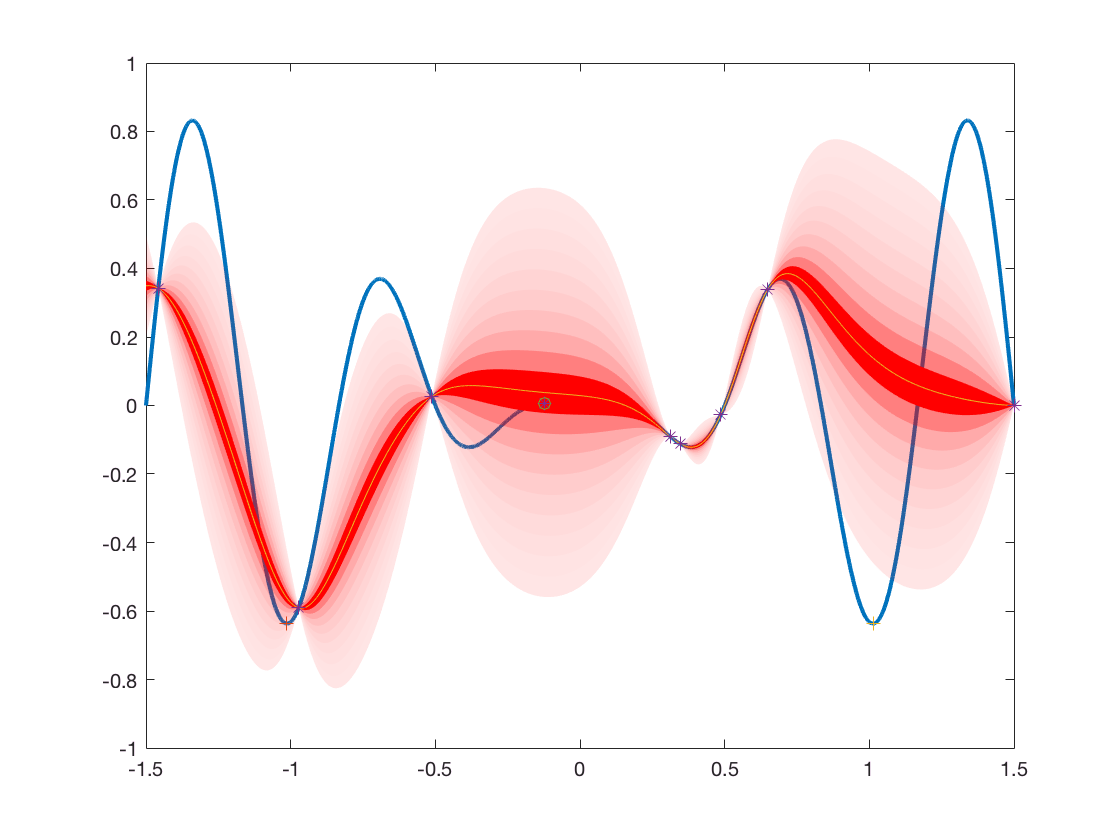

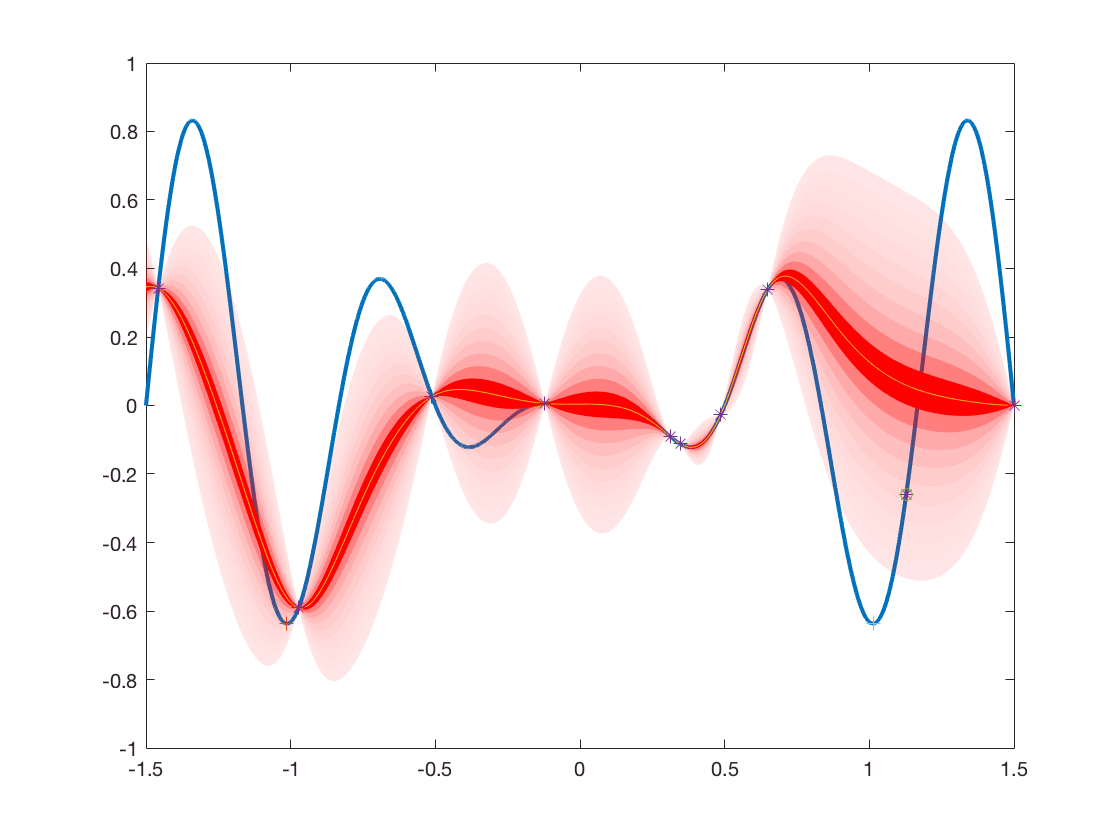

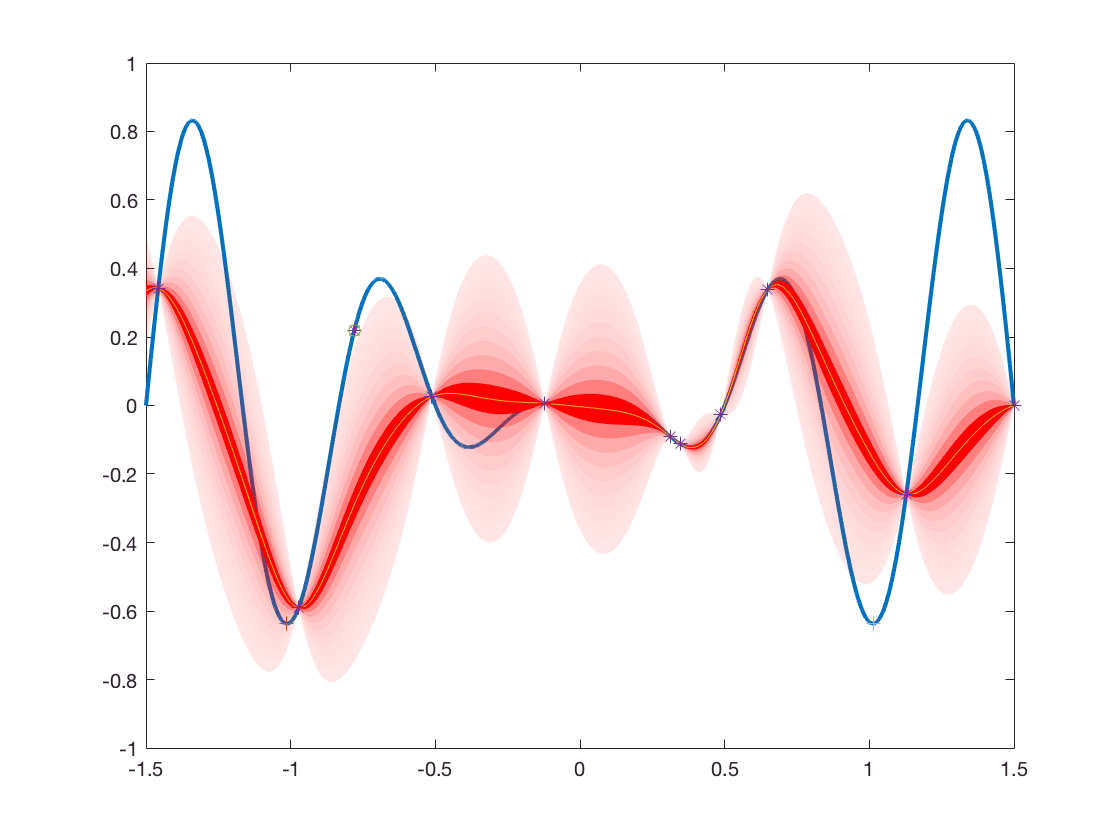

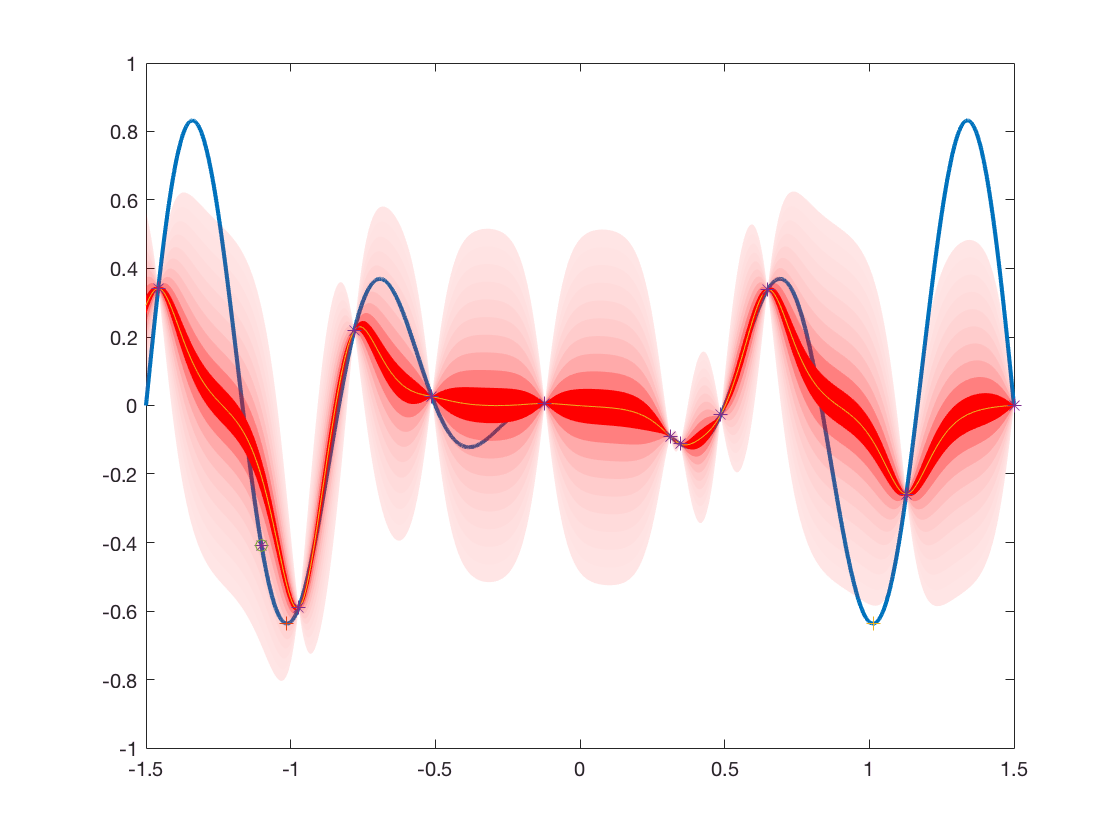

maxIter=maxIter-nInit;
% choose the initial design algorithm, e.g., lhd, uniform, etc

%obsX = lhsdesign(d, nInit)';
obsX = lhsdesign4grid(d, nInit, domain);
%obsX = unirnddesign4grid(d, nInit, domain);
obsY = zeros(size(obsX, 1), 1);

for k = 1:size(obsX, 1)
    obsY(k) = f(obsX(k, :));
end

% Bayesian optimization loop (for locating minimizer)
for k = 1:maxIter
    % criterial to evaluate in order to find where to sample next, this
    % can be replaced with other selection criteria (such as MPI, EI)    
    [nextX, dummy1, xTest, m, s, z, ef, h, et] = boLCB(domain, obsX, obsY, gps);
    
    % evaluate at the suggested point
    nextY = f(nextX);
    
    % save the measurement pair and CIs
    obsX = [obsX; nextX];
    obsY = [obsY; nextY];
    
    % visualize and update
    if visualize==1
        % 1D
        if d==1
            % visualize true function 1D
            y=f(xTest);
            h1=figure;
            plot(xTest,y,'LineWidth',2);
            hold on; plot(trueMinLoc,f(trueMinLoc),'+');
            % observations
            fu = [m+2*s; flip(m-2*s,1)];            
            for kk=2:10
                fu1(:,kk)=[m+2*s/(10-kk+1); flip(m+2*s/(10-kk+2),1)];
                fu1(:,kk+10)=[m-2*s/(10-kk+2); flip(m-2*s/(10-kk+1),1)];
            end
            fu1(:,1)=[m+2*s/10; flip(m,1)];
            fu1(:,11)=[m; flip(m-2*s/10,1)];
            for kk=1:10
                fu2(:,kk)=[m+2*kk*s/10; flip(m+2*(kk-1)*s/10,1)];
                fu2(:,kk+10)=[m-2*(kk-1)*s/10; flip(m-2*kk*s/10,1)];
            end
            for kk=1:10
                hold on; h2=fill([xTest; flip(xTest,1)], fu2(:,kk), [7 7 7]/8,'FaceColor','r','FaceAlpha',10/(10*kk)); % [7 7 7]/8
                h3=fill([xTest; flip(xTest,1)], fu2(:,kk+10), [7 7 7]/8,'FaceColor','r','FaceAlpha',10/(10*kk));
                %set(gcf,'windowbuttonmotionfcn','Fmotion( ([1 0]*get(gca,''currentp'')*[0;1;0] - min(ylim)) / diff(ylim) )');
                set(h2,'Linestyle','none')
                set(h3,'Linestyle','none')
            end
            hold on; plot(xTest, m); plot(obsX, obsY, '*');
            % current estimate
            hold on; plot(nextX, nextY,'o');
        end        
        % 2D
        if d==2
            h1=figure;
            plot(obsX(:,1),obsX(:,2), 'r+');
            for idx=1:size(obsX,1)
                text(obsX(idx,1)+0.2,obsX(idx,2)+0.2, num2str(idx),...
                    'FontWeight', 'bold',...
                    'FontSize',8,...
                    'HorizontalAlignment','center');
            end
            hold on; plot(trueMinLoc(:,1),trueMinLoc(:,2),'d');
            hold on; plot(nextX(:,1),nextX(:,2),'o');
            hold on; contour(unique(xTest(:,1)),unique(xTest(:,2)),reshape(f(xTest),size(unique(xTest(:,1)),1),size(unique(xTest(:,2)),1)));
            set(h1,'ShowText','on','TextStep',get(h,'LevelStep'))
            % true function 2D
            %h2=figure(2);surf(unique(xTest(:,1)),unique(xTest(:,2)),reshape(y,size(unique(xTest(:,1)),1),size(unique(xTest(:,2)),1)));
            h2=figure;surfc(unique(xTest(:,1)),unique(xTest(:,2)),reshape(m,size(unique(xTest(:,1)),1),size(unique(xTest(:,2)),1)));
            shading interp
        end
    end       
end

## Report what has been found

note the distance of the true minimum and the one BO4CO found after only *maxIter* observations!

[mv, mloc] = min(obsY);
fprintf('Minimum value: %f found at:\n', mv);

Minimum value: -0.630066 found at:


disp(obsX(mloc, :));

    1.0278



fprintf('True minimum value: %f at:\n', f(trueMinLoc));

True minimum value: -0.636816 at:


disp(trueMinLoc)

   -1.0127    1.0127

